# 엔트로피 정규화

by: 김덕우

date : 230413

## 환경변수 설정


clc; close all; clearvars
rng('default')

% 샘플수
n_sample = 5000;

% 소숫점 자리수
dicim = 2; % 디폴트

% 그래프 x 축 범위
x_lims = [0 1.5];


## 층용도 엔트로피 개념

일반적인 건물의 각 층별의 주용도는 

최대 8개라고 가정한 경우 Hx 최대값은 3이다.

주용도 2개가 균일하게 차지하는 경우, Hx 1

주용도 4개가 균일하게 차지하는 경우, Hx 2

## EXP: 데이터 생성

% 층용도가 3개인 경우
n_class = 3;
x_set3 = fn_rand_X(n_class, n_sample, dicim);
[~,Hx3] = fn_calc_Hx(x_set3);

% 층용도가 5개인 경우
n_class = 5;
x_set5 = fn_rand_X(n_class , n_sample, dicim);

[~,Hx5] = fn_calc_Hx(x_set5);

% 층용도가 7개인 경우
n_class = 7;
x_set7 = fn_rand_X(n_class, n_sample, dicim);
[~,Hx7] = fn_calc_Hx(x_set7);



### 엔트로피 확인

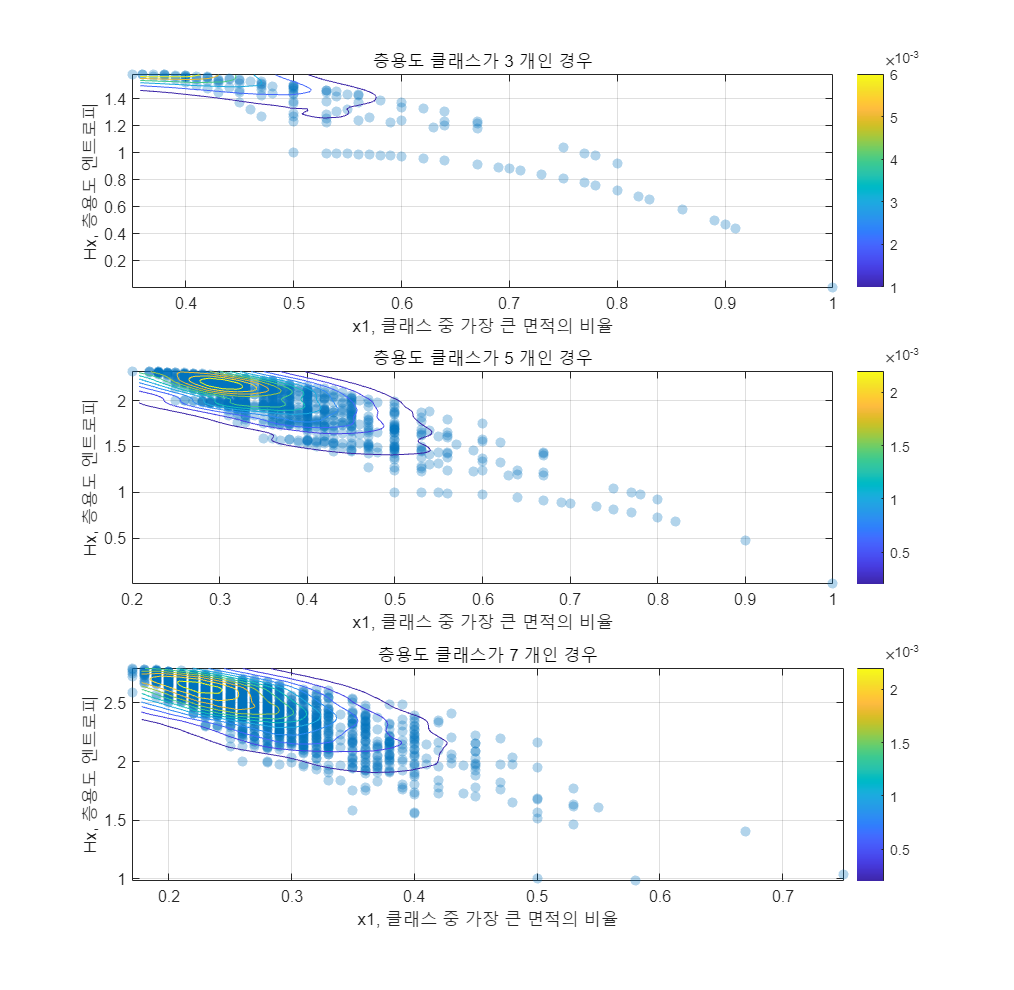


figure('units','normalized','outerPosition',[0.1 0.1 0.3 0.7])
subplot(3,1,1)
scatter(x_set3(:,1), Hx3,'filled',"o","MarkerFaceAlpha",0.3)
hold on
grid on
box on
dscatter(x_set3(:,1), Hx3,'plottype','contour') % surf','mesh'
colorbar;

xlabel('x1, 클래스 중 가장 큰 면적의 비율')
ylabel('Hx, 층용도 엔트로피')
title('층용도 클래스가 3 개인 경우')



subplot(3,1,2)
scatter(x_set5(:,1), Hx5,'filled',"o","MarkerFaceAlpha",0.3)
hold on
grid on
box on
dscatter(x_set5(:,1), Hx5,'plottype','contour') % surf','mesh'
colorbar;

xlabel('x1, 클래스 중 가장 큰 면적의 비율')
ylabel('Hx, 층용도 엔트로피')
title('층용도 클래스가 5 개인 경우')

subplot(3,1,3)
scatter(x_set7(:,1), Hx7,'filled',"o","MarkerFaceAlpha",0.3)
hold on
grid on
box on
dscatter(x_set7(:,1), Hx7,'plottype','contour') % surf','mesh'
colorbar;

xlabel('x1, 클래스 중 가장 큰 면적의 비율')
ylabel('Hx, 층용도 엔트로피')
title('층용도 클래스가 7 개인 경우')